clc
clear
close all; 

T = [3, 12, 25, 33, 42, 55, 70]';      % Temperature (Celsius)
R = [28034, 18419, 9637, 6998, 4915, 3117, 1890]'; % Resistance (Ohms)

% The equation is: R = R0 * exp( B * (1/(273.15+x) - 1/(273.15+25)) )
ft = fittype('R0 * exp(B * (1./(273.15 + x) - 1./(273.15 + 25)))', ...
             'independent', 'x', 'dependent', 'y');

opts = fitoptions(ft);
% Updated R0 guess to 10000 to match the Ohms scale of the data
opts.StartPoint = [3500, 10000]; % [B, R0]

[fitresult, gof] = fit(T, R, ft, opts);

vals = coeffvalues(fitresult);
names = coeffnames(fitresult);

for i = 1:length(names)
    if strcmp(names{i}, 'B')
        B_val = vals(i);
    elseif strcmp(names{i}, 'R0')
        R0_val = vals(i);
    end
end

fprintf('---------------------------------\n');

---------------------------------


fprintf('Fitted Constants:\n');

Fitted Constants:


fprintf('B  = %.4f\n', B_val);

B  = 3891.5751


fprintf('R0 = %.4f\n', R0_val);

R0 = 9953.4133


fprintf('Goodness of fit (R-squared): %.4f\n', gof.rsquare);

Goodness of fit (R-squared): 0.9995


fprintf('---------------------------------\n');

---------------------------------


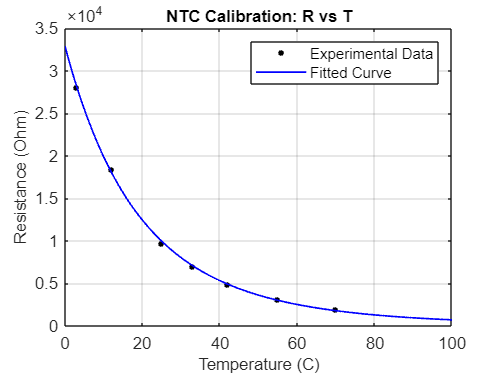


T_plot = 0:0.5:100;                 % Temperature range 0-100 C
R_model = feval(fitresult, T_plot); % Calculate Resistance from model

% Voltage Equation: V = R / (R + 10000) * 5
V_model = (R_model ./ (R_model + 1e4)) * 5;

% Apply Offset: Shift so 0 deg C is approx 0V (subtract 3.83)
V_offset = abs(V_model - 3.83);


figure(1);
plot(T, R, 'k.', 'MarkerSize', 10, 'LineWidth', 1); hold on;
plot(T_plot, R_model, 'b-', 'LineWidth', 1);
grid on;
xlabel('Temperature (C)', 'FontSize', 10);
ylabel('Resistance (Ohm)', 'FontSize', 10);
title(sprintf('NTC Calibration: R vs T'), 'FontSize', 10);
legend('Experimental Data', 'Fitted Curve', 'Location', 'NorthEast');

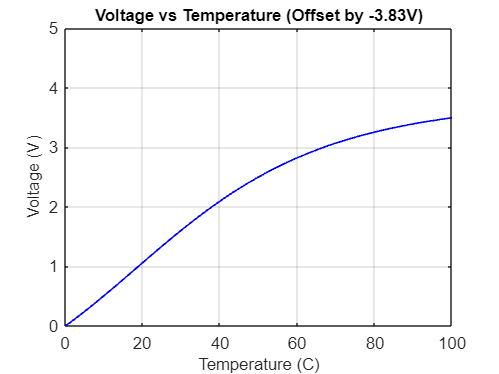


figure(2);
plot(T_plot, V_offset, 'b-', 'LineWidth', 1);
grid on;
xlabel('Temperature (C)', 'FontSize', 10);
ylabel('Voltage (V)', 'FontSize', 10);
title('Voltage vs Temperature (Offset by -3.83V)', 'FontSize', 10);
ylim([0 5]);